# Transfer Learning with MATLAB®

In this exercise, you will use transfer learning to classify images into 1 of 5 different food categories:

- Pizza

- Hot Dog

- Sushi

- French Fries

- Hamburger

## Are You in the Correct Directory?

% Run this to check
if isfolder('04-AdditionalFiles') && isfolder('04-Images')
    disp('You are in the correct directory. Please continue.')
    addpath(genpath(pwd))
else  
    disp('Please navigate to the proper Directory')
end

## Create a datastore

We used a datastore previously to read images in a loop. With [`ImageDatastore`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) you can also label images, set a custom read function and split images into different sets. 

Create a datastore, including subdirectories and add labels based on the filenames.

filePath = fullfile('04-Images');

imds = imageDatastore(filePath,...  
    'IncludeSubfolders',true,...
    'LabelSource','foldernames'); 

## Look at some random images

Let's get a feel for the dataset. 

numImages = numel(imds.Labels);
idx = randperm(numImages,16);
I = imtile(imds,Frames=idx);
figure
imshow(I)

## Extract the class names and the number of classes.

classNames = categories(imds.Labels)
numClasses = numel(classNames);

## Splitting Image datastore into 3 sets:  | Train | Validation | Test |

It is a best practice to split our data into a training, validation, and test set.

- Training - used to train our network by establishing proper weights that allow for accurate classification

- Validation - a dataset that you test the network on during training. If the results are poor, retrain the network with different hyperparameters and/or network architecture

- Test - an unseen dataset that is used as an unbiased measurement of network accuracy. Use this after you are happy with your validation performance.

There is not a perfect way to split your data, but people often do a 70/15/15 split. Use the [splitEachLabel](https://www.mathworks.com/help/matlab/ref/datastore.spliteachlabel.html) function to split your datastore into the three desired sets.

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,0.7,0.15,0.15,"randomized");

## Deep Network Designer

We will perform the entire [transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) workflow in the deep network designer (DND) app.

If you** cannot open DND**, open the script below

edit TransferLearningWithoutDND.mlx

#### Step 1: Import GoogLeNet

In transfer learning the majority of the layers stay the same. We need to modify the last few layers to fit our specific dataset. 

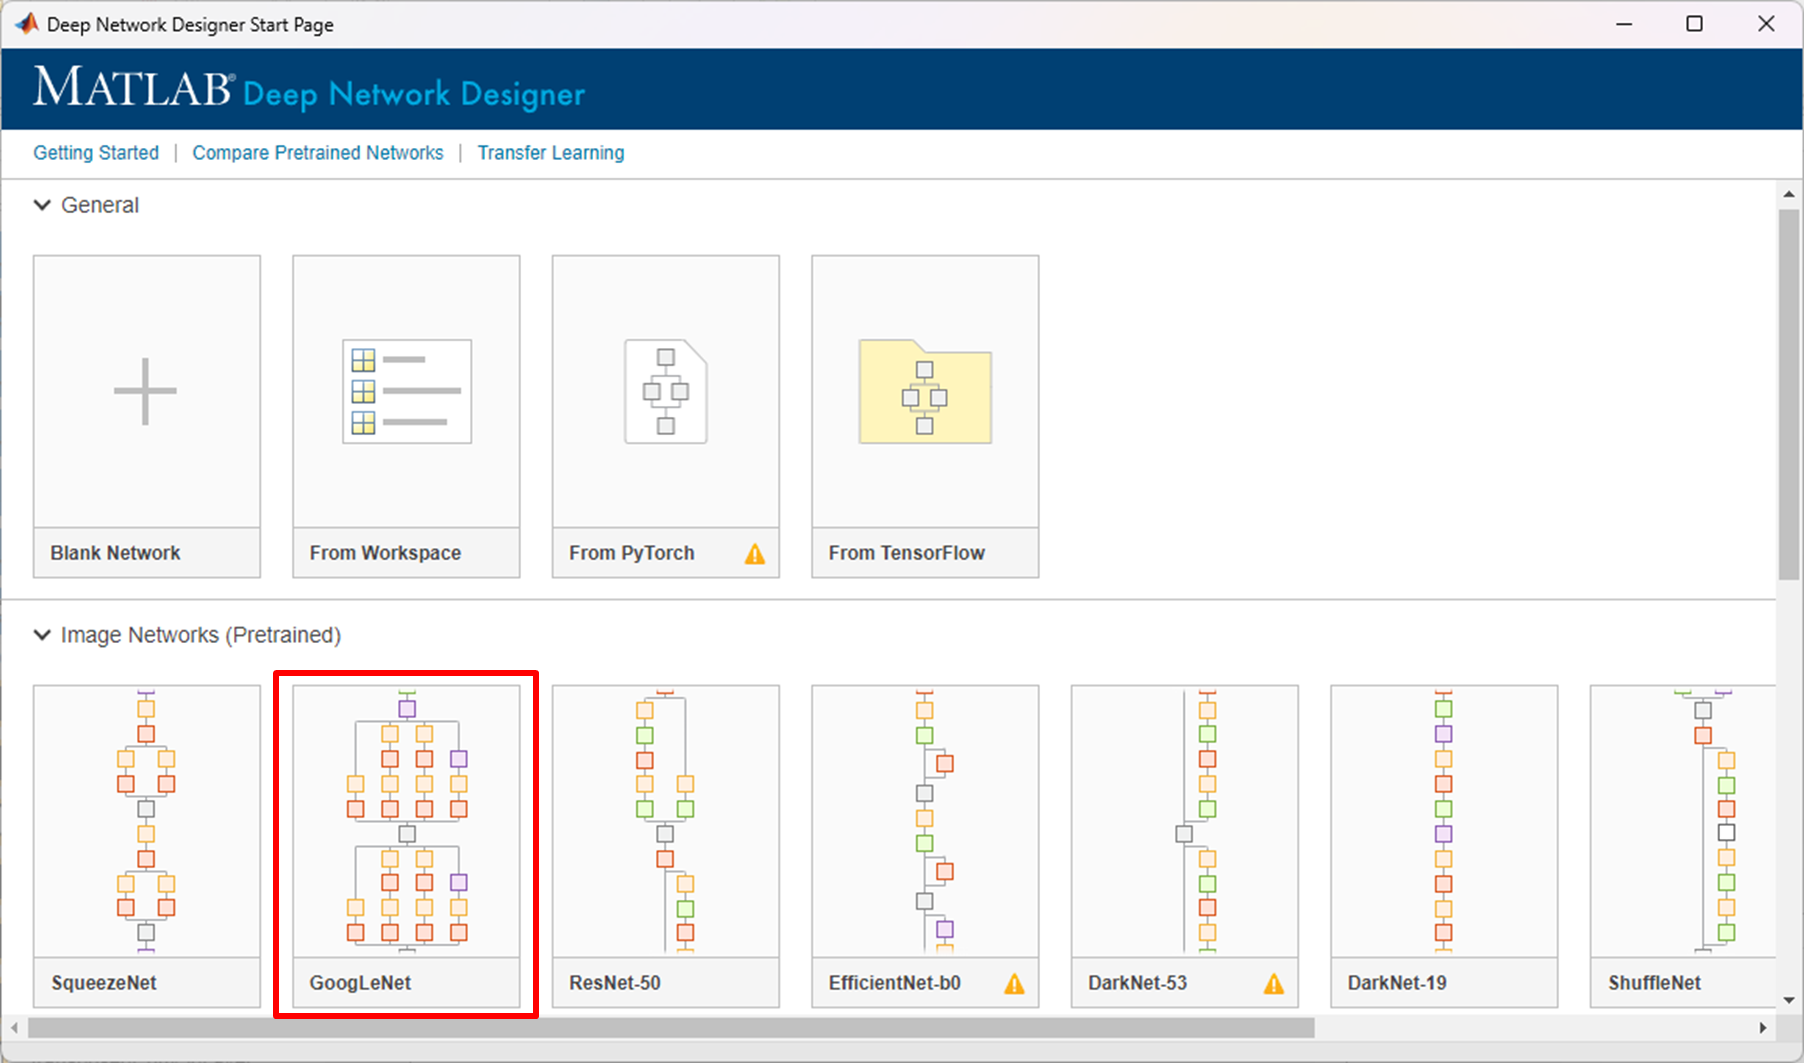

#### Step 2: Modify GoogLeNet

Instructions:

- Remove the last two layers in the network

- Add in a new Fully Connected Layer & Softmax Layer

- In the **fullyConnectedLayer**, change **OutputSize = 5**

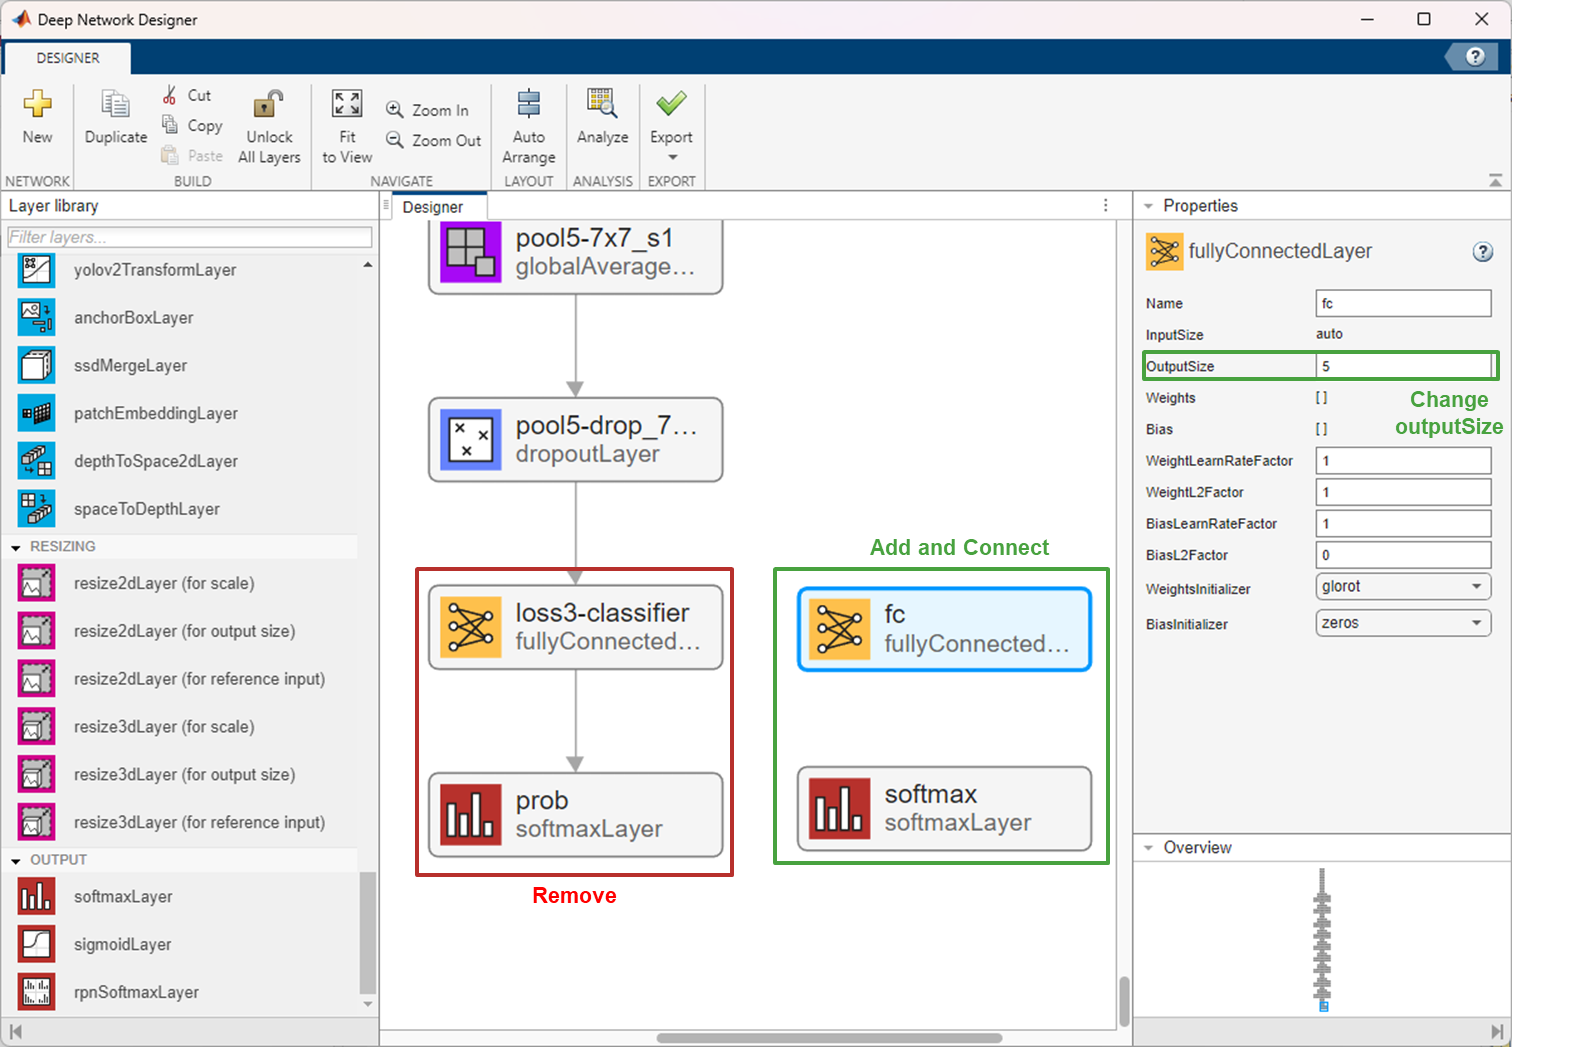

#### Step 3: Export network to workspace

Navigate to the Export button and select Export Network to workspace.  The app saves the network in the variable `net_1`.

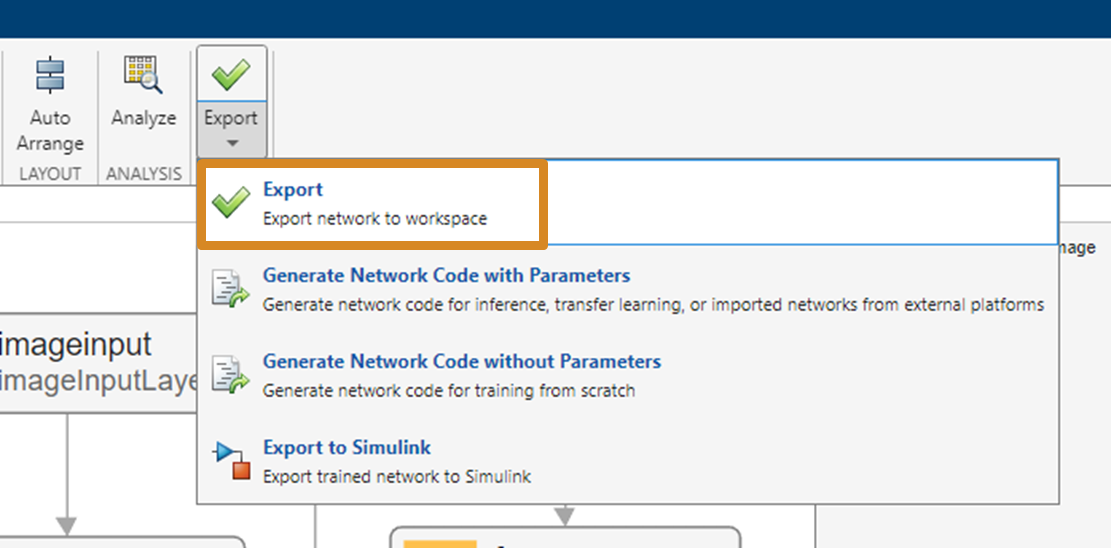

#### Step 4: Resize images for training, validation and testing

use augmentedImageDatastore resize the the images to matche the inputSize required by net_1

inputSize = net_1.Layers(1).InputSize

augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize,imdsTest);

#### Step 4: **Specify Training Options**

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](https://www.mathworks.com/help/deeplearning/ref/experimentmanager-app.html) app.

options = trainingOptions("sgdm", ...
    InitialLearnRate = 0.001, ...
    ValidationData = augimdsValidation, ...
    ValidationFrequency = 25, ...
    MaxEpochs = 5, ...
    MiniBatchSize = 32, ...
    ValidationPatience = 3, ...
    Plots = "training-progress", ...
    Metrics = "accuracy", ...
    Verbose = false);

#### Step 5: **Train Neural Network**

Train the neural network using the [`trainnet`](https://www.mathworks.com/help/deeplearning/ref/trainnet.html) function. Because the aim is classification, use cross-entropy loss.

net = trainnet(augimdsTrain,net_1,"crossentropy",options);

#### **Step 6: Save results**

save('04-AdditionalFiles/net_TransferLearning.mat','net')

## No GPU? No time to train? Run This.

if ~exist('net','var')
    disp('No trained network in workspace')
    disp('Load pretrained network')
    load('net_TransferLearning.mat')
end

## Test the Network

Once happy with validation results, test the network on the test dataset. Make predictions using the [`minibatchpredict`](https://www.mathworks.com/help/deeplearning/ref/minibatchpredict.html) function and convert the classification scores to labels using the [`scores2label`](https://www.mathworks.com/help/deeplearning/ref/scores2label.html) function.

- `Argument_1 = Trained Network `

- `Argument_2 = Resized Test Datastore `

% EDIT CODE BELOW
scores = minibatchpredict(Argument_1, Argument_2);
predictedLabels = scores2label(scores,classNames);

## Calculate Accuracy

Try to answer the following questions:

- Are there trends in misclassification?

- Where might these trends come from?

actualLabels = imdsTest.Labels;
accuracy = mean(predictedLabels == actualLabels)

% Confusion Matrix - visual inspection of accuracy and error
cm = confusionchart(predictedLabels, actualLabels);
cm.RowSummary = 'row-normalized';
cm.Title = 'Food Classification Confusion Matrix';

## View Some of the Results

Write a script that will let you view some of the images in the test dataset

randNum = randi(length(imdsTest.Files));
imOriginal = readimage(imdsTest,randNum);
imResized = imresize(imOriginal, inputSize(1:2));

actualLabel = imdsTest.Labels(randNum);
predictedScore = predict(net,single(imResized));
predictedLabel = scores2label(predictedScore, classNames)

imshow(imOriginal)
title(['Predicted: ' char(predictedLabel) '  Actual: ' char(actualLabel)],'Interpreter','none')

## Visualization

MATLAB lets you visualize weights in one of the network layers. We can see different convolution filters and activations. What do you notice?

View the different weights of the filters used for convolution

weights = net.Layers(2).Weights;
weights = mat2gray(weights);
montage(weights)
title('First convolutional layer weights')

View the activations in the first convolution layer

conv1Name = net.Layers(2).Name;
act1 = minibatchpredict(net, imResized, Outputs = conv1Name);

inputSize = size(act1);

act1 = reshape(act1,[inputSize(1), inputSize(2), 1, inputSize(3)]);
figure;montage(mat2gray(act1))
title('Activations of First Convolutional Layer')

*Copyright 2024 The MathWorks, Inc.*